# Extraction of edge segments

Compute suitable di�erential quantities that can be used as input data for the functions *zerocrosscurves* and *thresholdcurves*, so as to determine edges thresholded with respect to the gradient magnitude at arbitrary scale. When your function works satisfactorily, use it to extract edges from the images house and tools.

Try di�erent scales e.g. 0.0001, 1.0, 4.0, 16.0 and 64.0. For each image �find the best scale and adjust the threshold accordingly.

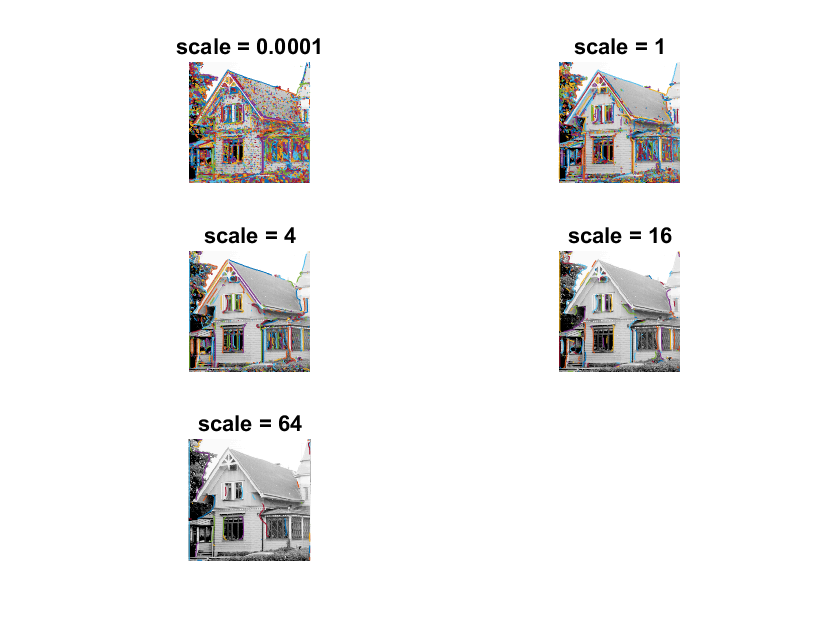

clear;
% house = godthem256;
% curves = edgecurves(house, 4, 3.5, 'same');
% overlaycurves(house, curves);

house = godthem256;
pos = 1;
%threshold = [0,1,4,8,20,2,3];
threshold = 3.5;
scales_array = [0.0001, 1.0, 4.0, 16.0, 64.0];
for scale = scales_array
    subplot(3,2,pos);
    curves_house = edgecurves(house, scale, threshold, 'same');
    overlaycurves(house, curves_house);
    title(['scale = ', num2str(scale)]);
    pos = pos + 1;
end

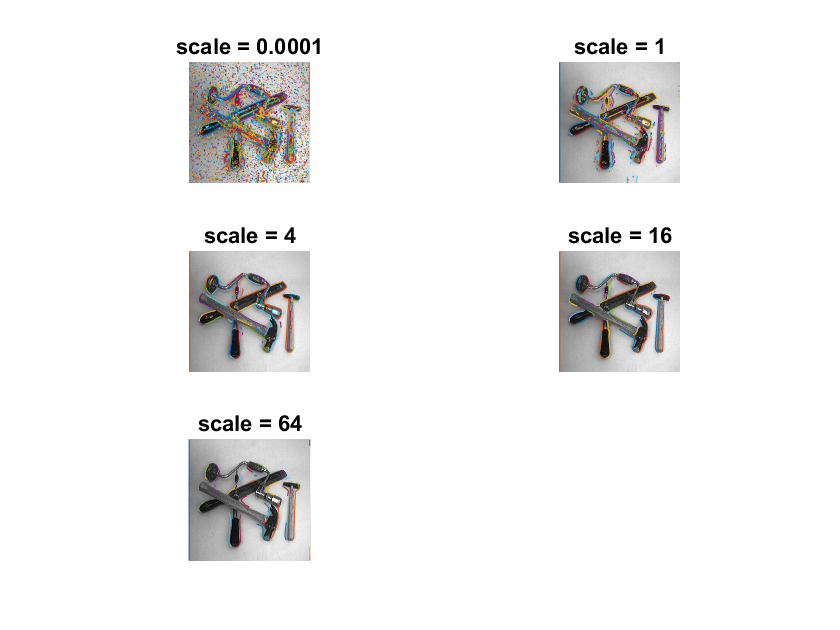

% tools = few256;
% curves = edgecurves(tools, 4, 8, 'same');
% overlaycurves(tools, curves);

pos = 1;tools = few256; 
threshold = 3.5;
for scale = scales_array
    subplot(3,2,pos);
    curves_tools = edgecurves(tools, scale, threshold, 'same');
    overlaycurves(tools, curves_tools);
    title(['scale = ', num2str(scale)]);
    pos = pos + 1;
end